# Figure 7A, 7B, 7C, S9C

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A058_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'RO DOX'     }    {[2 3 4]}    {[ 2]}    {[1]}    {[0]}
    {'2i DOX'     }    {[2 3 4]}    {[ 3]}    {[1]}    {[0]}
    {'RO+2i DOX'  }    {[2 3 4]}    {[ 4]}    {[1]}    {[0]}
    {'4/6i DOX'   }    {[2 3 4]}    {[ 5]}    {[1]}    {[0]}
    {'DMSO DOX'   }    {[2 3 4]}    {[ 6]}    {[1]}    {[0]}
    {'RO DMSO'    }    {[2 3 4]}    {[ 7]}    {[1]}    {[0]}
    {'2i DMSO'    }    {[2 3 4]}    {[ 8]}    {[1]}    {[0]}
    {'RO+2i DMSO' }    {[2 3 4]}    {[ 9]}    {[1]}    {[0]}
    {'4/6i DMSO'  }    {[2 3 4]}    {[10]}    {[1]}    {[0]}
    {'DMSO DMSO'  }    {[2 3 4]}    {[11]}    {[1]}    {[0]}
    {'500nM TAK'  }    {[5 6 7]}    {[ 2]}    {[1]}    {[0]}
    {'250nM TAK'  }    {[5 6 7]}    {[ 3]}    {[1]}    {[0]}
    {'125nM TAK'  }    {[5 6 7]}    {[ 4]}    {[1]}    {[0]}
    {'62.5nM TAK' }    {[5 6 7]}    {[ 5]}    {[1]}    {[0]}
    {'31.25nM TAK'}    {[5 6 7]}    {[ 6]}    {[1]}    {[0]}
    {'15.6nM TAK' }    {[5 6 7]}    {[ 7]}    {[1]}    {


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
   
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
                       apcExpressGate(n) = nanmean(dat.apcNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > 0.5 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < 0.1;
        end
     
       

    end
    S(i).apcExpressGate = apcExpressGate;
    

end 

7A


dose = [500 ;250 ;125; 62.5; 31.25; 15.6 ;6 ;3; 1; 0];
response = zeros(20, 1);

for i = 11:length(S)
    
    ind= ~isnan(S(i).POI(:,3)) & S(i).POI(:,3)>100 & S(i).POI(:,3)<123;
     sum(ind)
    xdata = S(i).POI(ind,3);
    cells = find(ind);
   
   
    for j = 1:length(cells)
        
        ydata(j) = (S(i).iRFP1(cells(j))/S(i).YFP1(cells(j)));
        
    
        
    end 
    response(i,1) = nanmean(ydata(1,:));

    clear ydata;
end 

ans = 638

ans = 693

ans = 844

ans = 918

ans = 956

ans = 858

ans = 862

ans = 1084

ans = 1143

ans = 1281

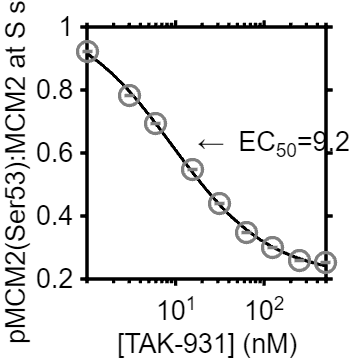


figure ('units','inches','position',[0 0 3 3])

doseResponse(dose,response(11:20),1);
xlabel('[TAK-931] (nM)');
ylabel('pMCM2(Ser53):MCM2 at S start');
xticks([0,10,100])


% print_pdf(['fig_7a.svg'])

7B

conds=[11:20];

timeGate = [0 20];
figure('Units', 'Inches', 'Position', [0, 0, 12, 8])

cdk_at_POI = NaN*ones(length(dat.POI(:,3)),length(conds));


for i = 1:length(conds)

    crlAct = S(conds(i)).POI(:,3);
     cdk2 = S(conds(i)).cdk;
    c = conds(i);
    data = S(c);

    inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,2)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
      data.apcExpressGate  & data.goodCdk & (data.POI_realtime(:,3)-data.POI_realtime(:,2)>0);
         sum(inds)

          crlAct = crlAct(inds,:);

         cdk2 = smoothdata(cdk2(inds,:),2,'sgolay',2);

         for n = 1:size(crlAct,1)
       
          cdk_at_POI(n,i) = cdk2(n,crlAct(n));
          end
 
cdk_threshold(i,1) = nanmean(cdk_at_POI(:,i));

end

ans = 1002

ans = 1338

ans = 1526

ans = 1498

ans = 1490

ans = 1274

ans = 1244

ans = 1381

ans = 1345

ans = 1530

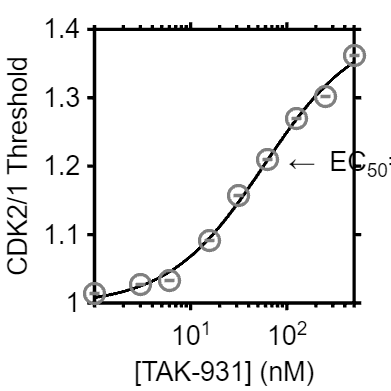


tak_dose = [500; 250; 125; 62.5;31.25;15.6;6;3;1;0];


figure ('units','inches','position',[0 0 3 3]);
dose = [500 ;250 ;125; 62.5; 31.25; 15.6 ;6 ;3; 1; 0];

doseResponse(dose,cdk_threshold,1);
xticks([0,10,100])
xlabel '[TAK-931] (nM)'
ylabel 'CDK2/1 Threshold'

% print_pdf(['fig_4D.svg'])

7C

conds=[11:20];
clear yvals1;

timeGate = [0 20];
figure ('color','white')

cdk_at_POI = NaN*ones(length(dat.POI(:,3)),length(conds));
apc_s = NaN*ones(length(dat.POI(:,3)),length(conds));

for i = 1:length(conds)

    crlAct = S(conds(i)).POI(:,3);
    apcinact = S(conds(i)).POI(:,2);
   
    cdk2 = S(conds(i)).cdk;
    c = conds(i);
    data = S(c);
  inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,2)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
      data.apcExpressGate  & data.goodCdk & (data.POI_realtime(:,3)-data.POI_realtime(:,2)>0);
sum(inds)

    crlAct = crlAct(inds,:);

    apcinact = apcinact(inds,:);


  cdk2 = smoothdata(cdk2(inds,:),2,'sgolay',2);



   for n = 1:size(crlAct,1)
       
if ~isnan((crlAct(n,1)-apcinact(n,1))/5) & ~isnan (double(cdk2(n,crlAct(n))))
    yvals1(n,1) = ((crlAct(n,1)-apcinact(n,1))/5);
 
end

       cdk_at_POI(n,i) = cdk2(n,crlAct(n));
      
   end
meanapc_s(i) = mean(yvals1);

cdk_threshold(i,1) = nanmean(cdk_at_POI(:,i));




end

ans = 1002

ans = 1338

ans = 1526

ans = 1498

ans = 1490

ans = 1274

ans = 1244

ans = 1381

ans = 1345

ans = 1530

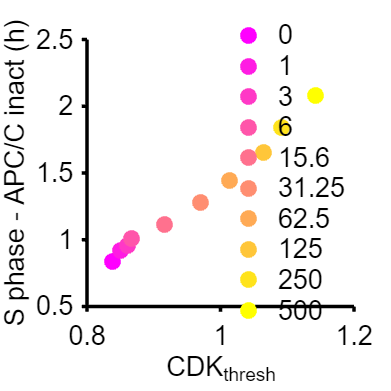


tak_dose = [500; 250; 125; 62.5;31.25;15.6;6;3;1;0];

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])

gscatter(cdk_threshold,meanapc_s,tak_dose,spring(10),'.',30);
axis square

xlim([.8 1.2])
ylim([.5  2.5])
yticks(0: .5 : 2.5)
set(gca,'box','off','fontsize',16,'linewidth',2)
ylabel([ 'S phase - APC/C inact (h)'],'FontSize',16)
xlabel ('CDK_{thresh}','FontSize',16)

legend('box','off','FontSize',16)


% print_pdf(['fig_7C.svg'])

S9C

conds=[11:20];
colors = [.6 .8 .1];

POI_align = 3;

ally2 = [];
clear cols
groups2=[];
clear yvals2;

timeGate = [0 20];

figure('Units', 'Inches', 'Position', [0, 0, 12, 8])
cdk_at_POI = NaN*ones(length(dat.POI(:,3)),length(conds));


for i = 1:length(conds)

    crlAct = S(conds(i)).POI(:,3);
    apcinact = S(conds(i)).POI(:,2);
    mitosis = S(conds(i)).POI(:,1);
    cdk2 = S(conds(i)).cdk;
    c = conds(i);
    data = S(c);

    inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,2)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
      data.apcExpressGate  & data.goodCdk & (data.POI_realtime(:,3)-data.POI_realtime(:,2)>0);
sum(inds)

    crlAct = crlAct(inds,:);
    mitosis = mitosis(inds,:);
  cdk2 = smoothdata(cdk2(inds,:),2,'sgolay',2);


  for n = 1:size(crlAct,1)
       
        if  ~isnan (double(cdk2(n,crlAct(n))))
          
             yvals2(n,1) = double(cdk2(n,crlAct(n)));
        
        end

       cdk_at_POI(n,i) = cdk2(n,crlAct(n));
    end

ally2 = [ally2; yvals2];

 groups2 = [groups2; repmat(i,size(yvals2))];

   
cdk_threshold(i,1) = nanmean(cdk_at_POI(:,i));


cols(i,1) = ({colors(1,:)}');

 groupcol = repmat([colors([1],:)],i,1);

end

ans = 1002

ans = 1338

ans = 1526

ans = 1498

ans = 1490

ans = 1274

ans = 1244

ans = 1381

ans = 1345

ans = 1530

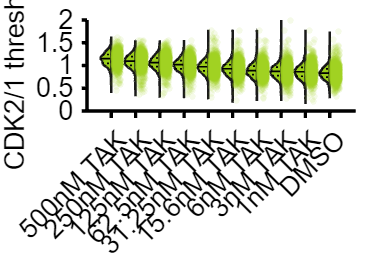


h = violinPlot((ally2),'groups',groups2, 'showMM',6,'histOpt',1.1,'divFactor',1,'histOri','left','widthDiv',[2 1],'color','black');
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups2)) + .1;
scatter(groups2+jit, (ally2), 15,groupcol(groups2,:),'filled','MarkerFaceAlpha',.10);
xticklabels(conditions(conds,1))
ylabel('CDK2/1 threshold')
tak_dose = [500; 250; 125; 62.5;31.25;15.6;6;3;1;0];
ylim ([0 2])
yticks(0:.5:2)


% print_pdf(['fig_S9C.svg'])